phase = -0.25;
t = linspace(0, 10, 500);
noise = rand(1,500);
clean = t+phase - round(t+phase);
% clean = abs(clean)-0.25;
% clean = 2*(t+phase) - round(2*(t+phase));
sig = clean * 1 + noise * 1;
sinn = sin(2 * pi * t);
coss = cos(2 * pi * t);

f1 = sig .* sinn;
g1 = sig .* coss;

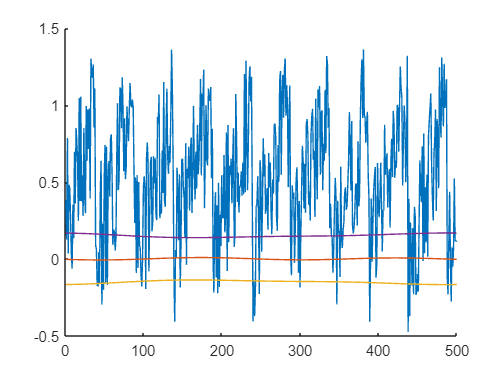

fltr = 2;

figure
hold on

plot(real(ifft(fft(sig, 500))))         % signal plot

                                        % -- SIN --
lockin = fft(f1, 500);                  % filtering
lockin(fltr:end-fltr) = 0;              

lockin = real(ifft(lockin));            % restoring
l = mean(lockin);

plot(lockin)
                                        % -- COS --
lockinA = fft(g1, 500);                 % filtering
lockinA(fltr:end-fltr) = 0;

lockinA = real(ifft(lockinA));          % restoring
lA = mean(lockinA);                   

plot(lockinA)

mes = sqrt(lockin.^2 + lockinA.^2);
plot(mes)

mean(mes);
sqrt(l ^2 + lA ^2)

ans = 0.1513